# 明確な因果関係はあるが(線形な)相関関係が認められない場合(2)

ばねにおもりをつけた運動（つり合いの位置を基準とし，空気抵抗は無いものとする）

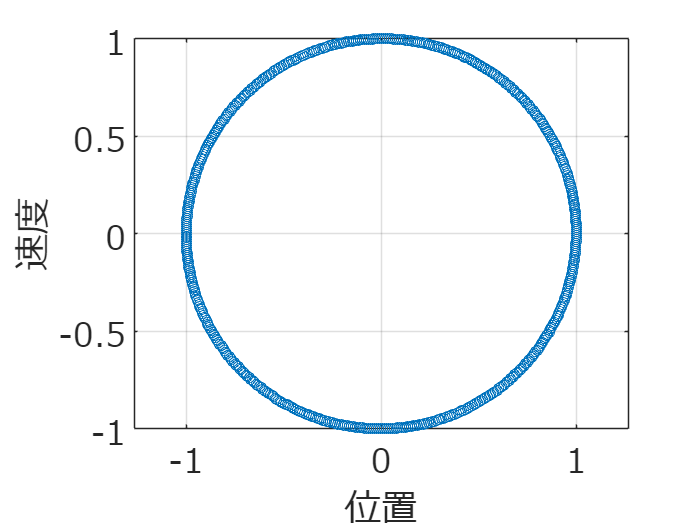

clear;clc;close all;
dt=0.01;
t=(0:dt:2*pi)';
a=[];v=[0];x=[1];
for n1=1:size(t,1)
    a=[a;-x(end)];
    v=[v;v(end)+dt*a(end)];
    x=[x;x(end)+dt*v(end)];
end

figure;
plot(x,v,'o');hold on;grid on;axis equal;
set(gca,'fontname','メイリオ','fontsize',20);
xlabel('位置');ylabel('速度');
exportgraphics(gcf,'fig_springMass_phase.pdf');

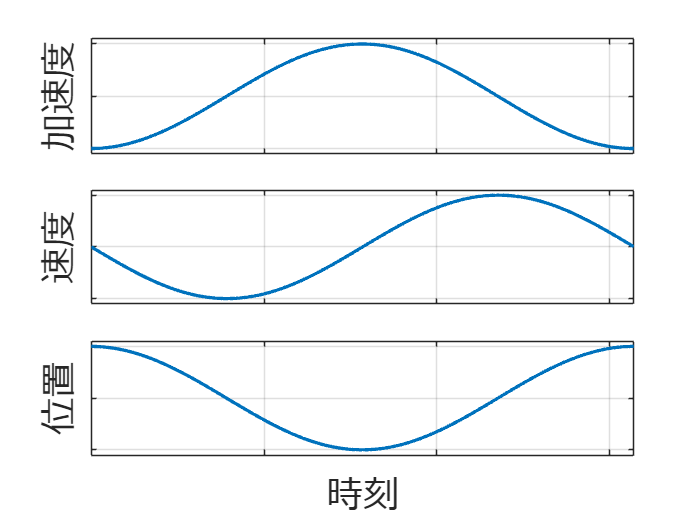


figure;
tiledlayout(3,1);
nexttile;

plot(t,a,'LineWidth',2);set(gca,'fontname','メイリオ','fontsize',20);grid on;
ylabel('加速度');xticklabels([]);yticklabels([]);ylim([-1.1 1.1]);
nexttile;

plot(t,v(1:end-1),'LineWidth',2);set(gca,'fontname','メイリオ','fontsize',20);grid on;
ylabel('速度');xticklabels([]);yticklabels([]);ylim([-1.1 1.1]);

nexttile;
plot(t,x(1:end-1),'LineWidth',2);set(gca,'fontname','メイリオ','fontsize',20);grid on;
ylabel('位置');
xlabel('時刻');xticklabels([]);yticklabels([]);ylim([-1.1 1.1]);
exportgraphics(gcf,'fig_springMass_stateVars.pdf');

位置と速度の相関係数

corr(x,v)

ans = 0.0050